% Comparative analysis on Synthetic Data
close all
clear

mouseName = 'M26';
recordingDate = 20180514; %imaging session
cDate = 20210618; %consolidation date
cRun = 1; %consolidation run number
workingOnServer = 0;

if workingOnServer
    HOME_DIR = '/home/bhalla/ananthamurthy/';
    ANALYSIS_DIR = strcat(HOME_DIR, 'Work/Analysis');
else
    HOME_DIR = '/Users/ananth/Documents/';
    HOME_DIR2 = '/Users/ananth/Desktop/';
    ANALYSIS_DIR = strcat(HOME_DIR2, 'Work/Analysis');
end

plotRefQ = 1;
plotAnalysedQs = 1;
plotDatasetCheck = 0;

addpath(genpath('/Users/ananth/Documents/MATLAB/CustomFunctions'))


%% Load Synthetic Data
if plotRefQ
    gDate = 20210324; %generation date
    gRun = 1; %generation run number
    nDatasets = 208;
    synthDataFilePath = sprintf('/Users/ananth/Desktop/Work/Analysis/Imaging/M26/20180514/synthDATA_%i_gRun%i_batch_%i.mat', gDate, gRun, nDatasets);
    load(synthDataFilePath)
end

%% Load Analysis Results
if plotAnalysedQs
    cDate = 20210514; %consolidation date
    cRun = 1; %consolidation run number
    analysisFilePath = sprintf('/Users/ananth/Desktop/Work/Analysis/Imaging/M26/20180514/M26_20180514_synthDataAnalysis_%i_cRun%i_cData.mat', cDate, cRun);
    load(analysisFilePath)
else
    cData = [];
end

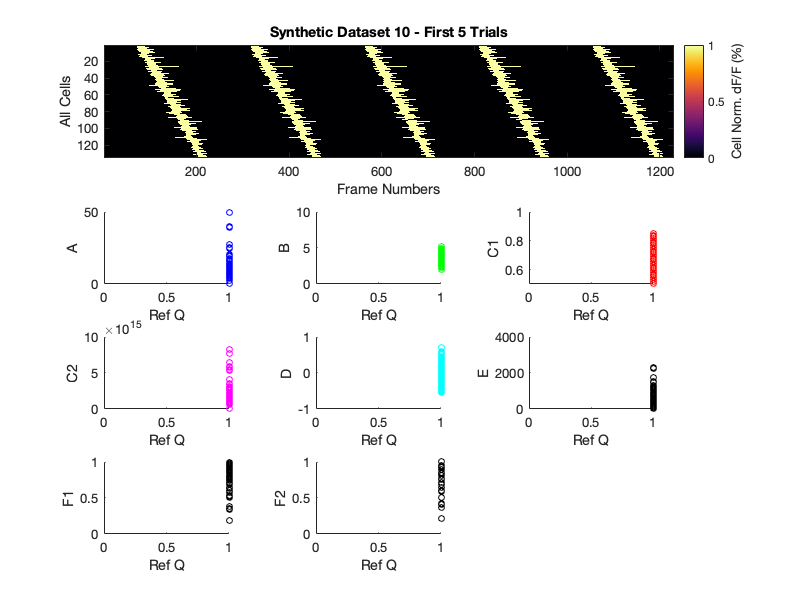

%% For single session
dnum = 10;
dfbf_2D = sdo_batch(dnum).syntheticDATA_2D;

normalizeScatterPlots = 0;  %for scatter plots
normalizeDataVisual = 1; % 0: global normalization; 1: cell-wise normalization

if normalizeDataVisual
    norm_dfbf_2D = zeros(size(dfbf_2D));
    for cell = 1:size(dfbf_2D)
        cellMax = max(squeeze(dfbf_2D(cell, :)));
        norm_dfbf_2D(cell, :) = dfbf_2D(cell, :)/cellMax;
    end
end

figureDetails = compileFigureDetails(13, 2, 10, 0.5, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
%Extra colormap options: inferno/plasma/viridis/magma

nCells = 135;
nFrames = 246;
nTrials = 5;
nMethods = 8;

fig1 = figure(1);
clf
set(fig1,'Position',[0, 200, 800, 600])
subplot(12, 9, 1:27) %Data visual
if normalizeDataVisual
    imagesc(norm_dfbf_2D(:, 1:nTrials*nFrames)*100);
    minVal = min(min(norm_dfbf_2D));
    maxVal = max(max(norm_dfbf_2D));
else
    imagesc(dfbf_2D(:, 1:nTrials*nFrames)*100);
    minVal = min(min(dfbf_2D));
    maxVal = max(max(dfbf_2D));
end
caxis([minVal maxVal]);
colormap(figureDetails.colorMap)
% title(sprintf('%i - First 5 Trials', recordingDate), ...
%     'FontSize', figureDetails.fontSize,...
%     'FontWeight', 'bold')
title(sprintf('Synthetic Dataset %i - First 5 Trials', dnum), ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
xlabel('Frame Numbers', ...
    'FontSize', figureDetails.fontSize)
ylabel('All Cells', ...
    'FontSize', figureDetails.fontSize)
z = colorbar;
if normalizeDataVisual
    ylabel(z,'Cell Norm. dF/F (%)', ...
        'FontSize', figureDetails.fontSize)
else
    ylabel(z,'dF/F (%)', ...
        'FontSize', figureDetails.fontSize)
end
set(gca,'FontSize', figureDetails.fontSize)

%Scatter plots
%C = distinguishable_colors(6);
if normalizeScatterPlots == 1
    for count = 1:nMethods
        x = sdo_batch(dnum).Q;
        if count == 1
            subplot(12, 9, [37:38, 46:47])
            y = cData.methodA.mAOutput_batch(dnum).normQ;
            scatter(x, y, 'b');
            ylabel('A', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 2
            subplot(12, 9, [40:41, 49:50])
            y = cData.methodB.mBOutput_batch(dnum).normQ;
            scatter(x, y, 'g');
            ylabel('B', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 3
            subplot(12, 9, [43:44, 52:53])
            y = cData.methodC.mCOutput_batch(dnum).normQ1;
            scatter(x, y, 'r');
            ylabel('C1', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 4
            subplot(12, 9, [64:65, 73:74])
            y = cData.methodC.mCOutput_batch(dnum).normQ2;
            scatter(x, y, 'm');
            ylabel('C2', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 5
            subplot(12, 9, [67:68, 76:77])
            y = cData.methodD.mDOutput_batch(dnum).normQ;
            scatter(x, y, 'c');
            ylabel('D', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 6
            subplot(12, 9, [70:71, 79:80])
            y = cData.methodE.mEOutput_batch(dnum).normQ;
            scatter(x, y, 'k');
            ylabel('E', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 7
            subplot(12, 9, [91:92, 100:101])
            y = cData.methodF.mFOutput_batch(dnum).normQ1;
            scatter(x, y, 'k');
            ylabel('F1', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 8
            subplot(12, 9, [94:95, 103:104])
            y = cData.methodF.mFOutput_batch(dnum).normQ2;
            scatter(x, y, 'k');
            ylabel('F2', ...
                'FontSize', figureDetails.fontSize)
        else
            str = {'Will add dataset','details here'};
            text(2,7,str)
        end
        xlabel('Ref Q', ...
            'FontSize', figureDetails.fontSize)
        xlim([0, 1])
        set(gca,'FontSize', figureDetails.fontSize)
    end
else %No normalization
    for count = 1:nMethods
        x = sdo_batch(dnum).Q;
        if count == 1
            subplot(12, 9, [37:38, 46:47])
            y = cData.methodA.mAOutput_batch(dnum).Q;
            scatter(x, y, 'b');
            ylabel('A', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 2
            subplot(12, 9, [40:41, 49:50])
            y = cData.methodB.mBOutput_batch(dnum).Q;
            scatter(x, y, 'g');
            ylabel('B', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 3
            subplot(12, 9, [43:44, 52:53])
            y = cData.methodC.mCOutput_batch(dnum).Q1;
            scatter(x, y, 'r');
            ylabel('C1', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 4
            subplot(12, 9, [64:65, 73:74])
            y = cData.methodC.mCOutput_batch(dnum).Q2;
            scatter(x, y, 'm');
            ylabel('C2', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 5
            subplot(12, 9, [67:68, 76:77])
            y = cData.methodD.mDOutput_batch(dnum).Q;
            scatter(x, y, 'c');
            ylabel('D', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 6
            subplot(12, 9, [70:71, 79:80])
            y = cData.methodE.mEOutput_batch(dnum).Q;
            scatter(x, y, 'k');
            ylabel('E', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 7
            subplot(12, 9, [91:92, 100:101])
            y = cData.methodF.mFOutput_batch(dnum).Q1;
            scatter(x, y, 'k');
            ylabel('F1', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 8
            subplot(12, 9, [94:95, 103:104])
            y = cData.methodF.mFOutput_batch(dnum).Q2;
            scatter(x, y, 'k');
            ylabel('F2', ...
                'FontSize', figureDetails.fontSize)
        else
        end
        xlabel('Ref Q', ...
            'FontSize', figureDetails.fontSize)
        xlim([0, 1])
        set(gca,'FontSize', figureDetails.fontSize)
    end
end
clear x
clear y
print(['/Users/ananth/Desktop/' ...
    'Figure4i_realData_' ...
    mouseName '_' num2str(recordingDate)], ...
    '-djpeg')

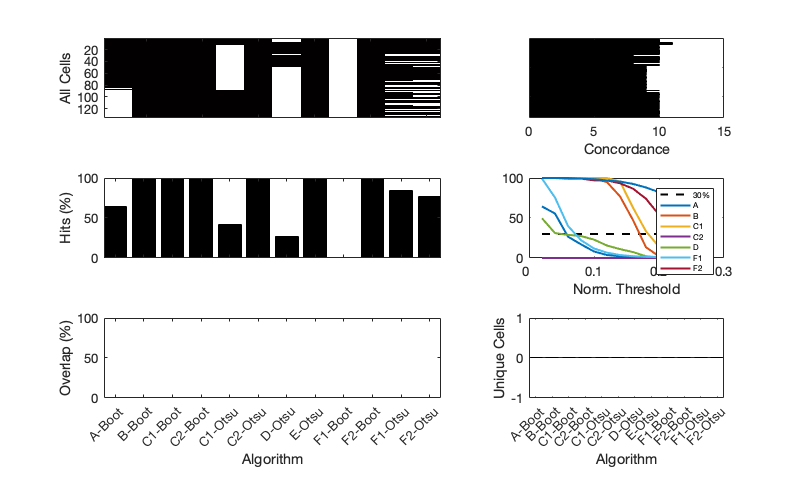


%% Classification
nAlgos = 12;
iddTimeCells = zeros(nCells, nAlgos);
allScores = zeros(nCells, nMethods);

%(fontSize, lineWidth, markerSize, transparency, colorMap)
figureDetails = compileFigureDetails(13, 2, 5, 0, 'hot'); %inferno/plasma/viridis/magma

for algo = 1:nAlgos
    if algo == 1
        iddTimeCells(:, algo) = squeeze(cData.methodA.mAOutput_batch(dnum).timeCells);
    elseif algo == 2
        iddTimeCells(:, algo) = squeeze(cData.methodB.mBOutput_batch(dnum).timeCells);
    elseif algo == 3
        iddTimeCells(:, algo) = squeeze(cData.methodC.mCOutput_batch(dnum).timeCells1);
    elseif algo == 4
        iddTimeCells(:, algo) = squeeze(cData.methodC.mCOutput_batch(dnum).timeCells2);
    elseif algo == 5
        iddTimeCells(:, algo) = squeeze(cData.methodC.mCOutput_batch(dnum).timeCells3);
    elseif algo == 6
        iddTimeCells(:, algo) = squeeze(cData.methodC.mCOutput_batch(dnum).timeCells4);
    elseif algo == 7
        iddTimeCells(:, algo) = squeeze(cData.methodD.mDOutput_batch(dnum).timeCells);
    elseif algo == 8
        iddTimeCells(:, algo) = squeeze(cData.methodE.mEOutput_batch(dnum).timeCells);
    elseif algo == 9
        iddTimeCells(:, algo) = squeeze(cData.methodF.mFOutput_batch(dnum).timeCells1);
    elseif algo == 10
        iddTimeCells(:, algo) = squeeze(cData.methodF.mFOutput_batch(dnum).timeCells2);
    elseif algo == 11
        iddTimeCells(:, algo) = squeeze(cData.methodF.mFOutput_batch(dnum).timeCells3);
    elseif algo == 12
        iddTimeCells(:, algo) = squeeze(cData.methodF.mFOutput_batch(dnum).timeCells4);
    end
end

fig2 = figure(2);
clf
set(fig2,'Position',[800, 200, 800, 500])
subplot(9, 9, [1:5, 10:14])
imagesc(iddTimeCells)
%colormap(figureDetails.colorMap)
colormap(gca, flipud(figureDetails.colorMap))
%colormap(flipud(hot))
%caxis([0 1.1])
%title(sprintf('Classification | Real Data - %i', date))
xticklabels({})
% xlabel('Algorithm', ...
%     'FontSize', figureDetails.fontSize-5, ...
%     'FontWeight', 'bold')
% xticklabels({'A-Boot', 'B-Boot', 'C1-Boot', 'C2-Boot', 'C1-Otsu', 'C2-Otsu', 'D-Otsu', 'E-Otsu', 'F1-Boot', 'F2-Boot', 'F1-Otsu', 'F2-Otsu'})
% xtickangle(45)
ylabel('All Cells', ...
    'FontSize', figureDetails.fontSize)
set(gca, 'FontSize', figureDetails.fontSize)

methodHits = zeros(nCells, 1);
for cell = 1:nCells
    methodHits(cell, 1) = numel(find(iddTimeCells(cell, :)));
end
subplot(9, 9, [7:9, 16:18])
%imagesc(methodHits*100/nAlgos)
barh(methodHits, 'black')
set(gca, 'YDir','reverse')
%title('Concordance')
%xticklabels({})
xlabel('Concordance', ...
    'FontSize', figureDetails.fontSize)
yticklabels({})
set(gca, 'FontSize', figureDetails.fontSize)

percentHits = nansum(iddTimeCells, 1)*100/nCells;
subplot(9, 9, [28:32, 37:41])
%plot(percentHits, 'bo', 'MarkerSize', 10)
bar(percentHits, 'black')
axis tight
xticklabels({})
% xlabel('Algorithm', ...
%     'FontSize', figureDetails.fontSize-5, ...
%     'FontWeight', 'bold')
% xticklabels({'Ar', 'Br', 'C1r', 'C2r', 'C1o', 'C2o', 'Do', 'F1r', 'F2r', 'F1o', 'F2o'})
% xtickangle(45)
ylim([0 100])
ylabel('Hits (%)', ...
    'FontSize', figureDetails.fontSize)
set(gca, 'FontSize', figureDetails.fontSize)

for method = 1:nMethods
    if method == 1
        allScores(:, method) = squeeze(cData.methodA.mAOutput_batch(dnum).normQ);
    elseif method == 2
        allScores(:, method) = squeeze(cData.methodB.mBOutput_batch(dnum).normQ);
    elseif method == 3
        allScores(:, method) = squeeze(cData.methodC.mCOutput_batch(dnum).normQ1);
    elseif method == 4
        allScores(:, method) = squeeze(cData.methodC.mCOutput_batch(dnum).normQ2);
    elseif method == 5
        allScores(:, method) = squeeze(cData.methodD.mDOutput_batch(dnum).normQ);
    elseif method == 6
        allScores(:, method) = squeeze(cData.methodE.mEOutput_batch(dnum).normQ);
    elseif method == 7
        allScores(:, method) = squeeze(cData.methodF.mFOutput_batch(dnum).normQ1);
    elseif method == 8
        allScores(:, method) = squeeze(cData.methodF.mFOutput_batch(dnum).normQ2);
    end
end
estimatedPercentHits = zeros(numel(0:0.1:1), nMethods);
count = 0;
for thresh = 0:0.1:1
    count = count+1;
    for method = 1:nMethods
        estimatedPercentHits(count, method) = (numel(find(allScores(:, method)>thresh))*100)/nCells;
    end
end
subplot(9, 9, [34:36, 43:45])
thirtyPercentLine = 30*(ones(11, 1));
plot(thirtyPercentLine, '--k', 'LineWidth', figureDetails.lineWidth, 'MarkerSize', figureDetails.markerSize)
hold on
plot(estimatedPercentHits, 'LineWidth', figureDetails.lineWidth, 'MarkerSize', figureDetails.markerSize)
hold off
% title('Classification vs Threshold')
xticklabels({0:0.1:1})
xlabel('Norm. Threshold', ...
    'FontSize', figureDetails.fontSize)
set(gca, 'FontSize', figureDetails.fontSize)
lgd = legend('30%', 'A', 'B', 'C1', 'C2', 'D', 'F1', 'F2');
lgd.FontSize = figureDetails.fontSize-5;

%in comparison to F2r
compN = sum(iddTimeCells(:, 10));
percentOverlap(1) = dot(iddTimeCells(:, 1), iddTimeCells(:, 9))*100/compN;
percentOverlap(2) = dot(iddTimeCells(:, 2), iddTimeCells(:, 9))*100/compN;
percentOverlap(3) = dot(iddTimeCells(:, 3), iddTimeCells(:, 9))*100/compN;
percentOverlap(4) = dot(iddTimeCells(:, 4), iddTimeCells(:, 9))*100/compN;
percentOverlap(5) = dot(iddTimeCells(:, 5), iddTimeCells(:, 9))*100/compN;
percentOverlap(6) = dot(iddTimeCells(:, 6), iddTimeCells(:, 9))*100/compN;
percentOverlap(7) = dot(iddTimeCells(:, 7), iddTimeCells(:, 9))*100/compN;
percentOverlap(8) = dot(iddTimeCells(:, 8), iddTimeCells(:, 9))*100/compN;
percentOverlap(9) = dot(iddTimeCells(:, 9), iddTimeCells(:, 9))*100/compN;
percentOverlap(10) = dot(iddTimeCells(:, 10), iddTimeCells(:, 9))*100/compN;
percentOverlap(11) = dot(iddTimeCells(:, 11), iddTimeCells(:, 9))*100/compN;
percentOverlap(12) = dot(iddTimeCells(:, 12), iddTimeCells(:, 9))*100/compN;

%subplot(9, 9, [64:68, 73:77])
subplot(9, 9, [55:59, 64:68])
bar(percentOverlap, 'black')
axis tight
%xticks(1:11)
xlabel('Algorithm', ...
    'FontSize', figureDetails.fontSize)
xticklabels({'A-Boot', 'B-Boot', 'C1-Boot', 'C2-Boot', 'C1-Otsu', 'C2-Otsu', 'D-Otsu', 'E-Otsu', 'F1-Boot', 'F2-Boot', 'F1-Otsu', 'F2-Otsu'})
xtickangle(45)
ylim([0 100])
ylabel('Overlap (%)', ...
    'FontSize', figureDetails.fontSize)
set(gca, 'FontSize', figureDetails.fontSize)

nFactors = 11;
unique = zeros(algo, numel(1:1:nFactors));
count = 0;
for factor = 1:2:nFactors
    count = count + 1;
    cellList = find(methodHits==factor);
    for listi = 1:numel(cellList)
        for algo = 1:nAlgos
            if iddTimeCells(listi, algo)
                unique(algo, count) = unique(algo, count) + 1;
            end
        end
    end
end
subplot(9, 9, [61:63, 70:72])
bar(unique(:, 1), 'k')
axis tight
xlabel('Algorithm', ...
    'FontSize', figureDetails.fontSize)
xticklabels({'A-Boot', 'B-Boot', 'C1-Boot', 'C2-Boot', 'C1-Otsu', 'C2-Otsu', 'D-Otsu', 'E-Otsu', 'F1-Boot', 'F2-Boot', 'F1-Otsu', 'F2-Otsu'})
xtickangle(45)
ylabel('Unique Cells', ...
    'FontSize', figureDetails.fontSize)
set(gca,'FontSize', figureDetails.fontSize)
print(['/Users/ananth/Desktop/' ...
    'Figure4ii_synthData_' ...
    mouseName '_' num2str(recordingDate)], ...
    '-djpeg')


% %% Supplementary
% fig3 = figure(3);
% set(fig3,'Position',[0, 200, 800, 800])
% imagesc(unique)
% %plot(unique')
% %surf(unique)
% %colormap(figureDetails.colorMap)
% colormap(gca, plasma())
% %xlim([0 7])
% %ylim([0 nAlgos+1])
% %plot(unique)
% % title('Uniquely Identified Time Cells', ...
% %     'FontSize', figureDetails.fontSize, ...
% %     'FontWeight', 'bold')
% xticklabels({'1', '2', '3', '4', '5', '6', '7', '8', '9', '10', '11'})
% %axis tight
% xlabel('Concordance Order', ...
%     'FontSize', figureDetails.fontSize)
% % ylabel('Algorithm', ...
% %     'FontSize', figureDetails.fontSize)
% yticklabels({'Ar', 'Br', 'C1r', 'C2r', 'C1o', 'C2o', 'Do', 'F1r', 'F2r', 'F1o', 'F2o'})
% z = colorbar;
% ylabel(z, 'Number of Cells', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
% set(gca, 'FontSize', figureDetails.fontSize)
% print(['/Users/ananth/Desktop/' ...
%     'Figure4sup_synthData_' ...
%     mouseName '_' num2str(recordingDate)], ...
%     '-djpeg')
